# **디지털신호처리 ****HW#2**

Due date : 2021.12.22. 23:59

**이름**** : 박종서    **

**학번**** : 201710919**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 :  https://github.com/jongseopark0/DSP-hw/tree/master**

1. 이산 비주기 신호 $x\left\lbrack n\right\rbrack =\left\lbrace \underset{\uparrow }{1} ,2,2,1\right\rbrace$에 대하여 다음을 구하라.

1) 4점 DFT 및 IDFT를 수행하라. 그리고 DFT의 결과를 DTFT와 비교하라. 

x=[1,2,2,1];
N=4;
X=dft(x,N);
magDTF =abs(X);
angleDTF = angle(X)*180/pi;


IX = idft(X,N);

magIDFT =abs(IX);
angleIDFT = angle(IX)*180/pi;

w = 0:1:3;
Xd = 1 + 2*exp(-j*w) + 2*exp(-j*2*w) + exp(-j*3*w);

magDTFT = abs(Xd);
angleDTFT = angle(Xd)*180/pi;
magDTF

magDTF =     6.0000    1.4142    0.0000    1.4142


angleDTF 

angleDTF =          0 -135.0000  -90.0000  135.0000


magIDFT

magIDFT =     1.0000    2.0000    2.0000    1.0000


angleIDFT

angleIDFT = 	1.0e+-13 *

   -0.1908   -0.0167    0.0285    0.1387


magDTFT

magDTFT =     6.0000    3.6518    0.1812    0.1386


angleDTFT

angleDTFT =          0  -85.9437 -171.8873  -77.8310


2) 영 채우기를 시행하여 같은 신호에 대해 16점 DFT 및 IDFT를 수행하라.

x=[1,2,2,1,zeros(1,12)];
N=16;

X=dft(x,N);

magDFT16 = abs(X);
angleDFT16 = angle(X)*180/pi;

IX2 = idft(X,N);

magIDFT = abs(IX2);
angleIDFT = angle(IX2)*180/pi;

magDFT16

magDFT16 =     6.0000    5.5861    4.4609    2.9357    1.4142    0.2607    0.3170    0.3308    0.0000    0.3308    0.3170    0.2607    1.4142    2.9357    4.4609    5.5861


angleDFT16

angleDFT16 =          0  -33.7500  -67.5000 -101.2500 -135.0000 -168.7500  -22.5000  -56.2500   90.0000   56.2500   22.5000  168.7500  135.0000  101.2500   67.5000   33.7500


magIDFT

magIDFT =     1.0000    2.0000    2.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


angleIDFT

angleIDFT =     0.0000    0.0000   -0.0000   -0.0000  -29.6878  -49.8645  -48.1221  -65.8068  -76.7888  -86.0091  -95.8263 -106.0154 -121.9136 -130.3141 -146.9043 -156.5014


2. (P5.2) DFS의 정의를 사용하여 다음 주기 신호의 DFS 계수를 구하고, MATLAB을 사용하여 검증하라.

1) $\tilde{x_1 } \left(n\right)=\left\lbrace 4,1,-1,1\right\rbrace ,N=4$

XK0 = 4+1-1+1

XK0 = 5

XK1 = 4-j+1+j

XK1 = 5

XK2 = 4-1-1-1

XK2 = 1

XK3 = 4+j+1-j

XK3 = 5

N=4;
xn = [4,1,-1,1];
Xk = dfs(xn,N)

Xk =    5.0000 + 0.0000i   5.0000 + 0.0000i   1.0000 - 0.0000i   5.0000 + 0.0000i


2) $\tilde{x_2 } \left(n\right)=\left\lbrace 1,0,-1,-1,0\right\rbrace ,N=5$

XK20 = 1-1-1

XK20 = -1

XK21 = 1-exp(-j*4*pi/5)-exp(-j*6*pi/5)

XK21 = 2.6180 + 0.0000i

XK22 = 1-exp(-j*8*pi/5)-exp(-j*12*pi/5)

XK22 = 0.3820 - 0.0000i

XK23 = 1-exp(-j*12*pi/5)-exp(-j*18*pi/5)

XK23 = 0.3820 - 0.0000i

XK24 = 1-exp(-j*16*pi/5)-exp(-j*24*pi/5)

XK24 = 2.6180 + 0.0000i

N2=5;
xn2 = [1,0,-1,-1,0];
Xk2 = dfs(xn2,N2)

Xk2 =   -1.0000 + 0.0000i   2.6180 + 0.0000i   0.3820 - 0.0000i   0.3820 + 0.0000i   2.6180 + 0.0000i


3.  (P5.10) 아래와 같이 주어진 유한 길이 신호를 고려하자.


$$x\left(n\right)=\left\lbrace \begin{array}{ll}
{\textrm{sinc}}^2 \left\lbrace \frac{\left(n-50\right)}{2}\right\rbrace  & 0\le n\le 100\\
0 & \textrm{otherwise}
\end{array}\right.$$


1) x(n)의 DFT X(k)를 구하라. (stem 함수를 사용하여) 그것의 크기 및 위상 그래프를 그려라. 

n = 0:1:100;
k = 0:1:100;
xn = sinc((n-50)/2).^2;
Xk=dft(xn,length(n));

figure(6)
subplot(2,1,1);
stem(k,abs(Xk));
title("DFT 크기");

subplot(2,1,2);
stem(k,angle(Xk)/pi);
title("DFT 위상");

2) MATLAB을 사용하여 x(n)의 DTFT $X\left(e^{j\omega } \right)$의 크기 및 위상 그래프를 그려라.

n=0:1:100;
xn2 = sinc((n-50)/2).^2;
k=0:10:1000;
w=(pi/500)*k;
XD=xn2*(exp(-j*pi/500)).^(n'*k);

figure(7)
subplot(2,1,1);
plot(k/10,abs(XD));
title("DTFT 크기");
subplot(2,1,2);


stem(k/10,angle(XD)*180/pi);
title("DTFT 위상");

3) 위 DFT는 $X\left(e^{j\omega } \right)$의 샘플링된 변형임을 검증하라. hold 함수 (hold on;) 를 사용해서 두 그래프를 합치도록 한다.

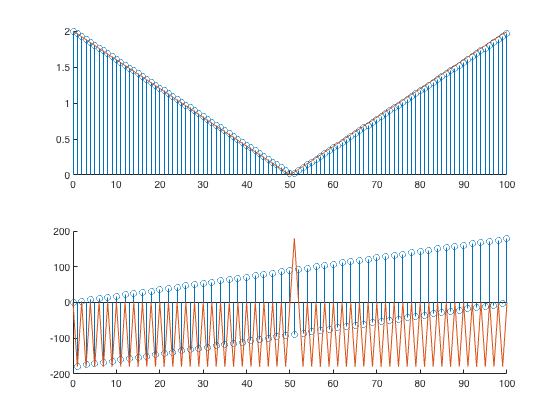

n = 0:100; 
xn = sinc((n-50)/2).^2; 
N = length(xn); 
Xk = dft(xn,N); 
k = 0:N-1; 
magk = abs(Xk); 
anglek = angle(Xk)*180/pi;
figure(8)
subplot(2,1,1);
hold on 
stem(k,magk); 

subplot(2,1,2); 
hold on
stem(k,anglek); 
subplot(2,1,1);
plot(k,abs(XD));
hold off
subplot(2,1,2);
plot(k,angle(XD)*180/pi);
hold off

4) DFT $X\left(k\right)$로부터 DTFT $X\left(e^{j\omega } \right)$를 재구성할 수 있는가? 가능하다면, 재구성에 필요한 보간 공식을 구하라. 가능하지 않다면, 그 이유를 기술하라.

% 주파수 영역에서의 샘플 개수가 신호의 크기보다 크거나 같으면 x(n)의 푸리에 변환 x(e^jw)는 이 샘플 값으로부터 재구성 할
% 수 있다.

% x(n)의 신호개수는 101개이고, 샘플개수도 101개 이므로 X(e^jw)로의 재구성 가능하다.

function [Xk] =dft(xn, N)
n=[0:1:N-1];
k=[0:1:N-1];
WN = exp(-j*2*pi/N);
nk=n'*k;
WNnk=WN.^nk;
Xk=xn*WNnk;
end

function [xn] =idft(Xk, N)
n=[0:1:N-1];
k=[0:1:N-1];
WN = exp(-j*2*pi/N);
nk=n'*k;
WNnk=WN.^(-nk);
xn=(Xk*WNnk)/N;
end

function [Xk] =dfs(xn, N)
n=[0:1:N-1];
k=[0:1:N-1];
WN = exp(-j*2*pi/N);
nk=n'*k;
WNnk=WN.^nk;
Xk=xn*WNnk;
end

function [xn] =idfs(Xk, N)
n=[0:1:N-1];
k=[0:1:N-1];
WN = exp(-j*2*pi/N);
nk=n'*k;
WNnk=WN.^(-nk);
xn=(Xk*WNnk)/N;
end